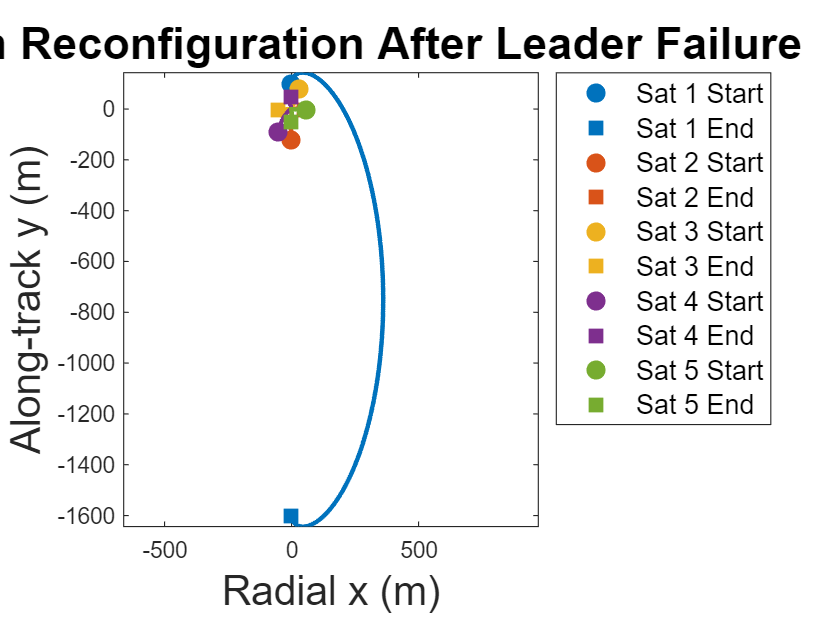

%% ========================================================================
%  SIM_05_LeaderFailure_SwarmReconfig
%  --------------------------------------------------------------
%  - Simulates 5-satellite swarm where central leader fails mid-mission.
%  - Remaining 4 satellites reconfigure into a new cross formation.
%  - Leader holds its position (no control), others minimize DeltaV.
%  - Trajectory and DeltaV plots are generated.
%
%  Author: Sabrina Nicacio
% ========================================================================

clc; clear; close all;

%% === ORBIT PARAMETERS ===
mu = 3.986e14;
Re = 6371e3;
alt = 500e3;
a = Re + alt;
n = sqrt(mu / a^3);

T = 2*pi / n;
N_orbits = 1;
dt = 10;
N = round(N_orbits * T / dt);
t_vec = (0:N-1)*dt;

%% === SYSTEM MATRICES ===
A = [  0     0     0     1     0     0;
       0     0     0     0     1     0;
       0     0     0     0     0     1;
     3*n^2   0     0     0   2*n     0;
       0     0     0  -2*n     0     0;
       0     0  -n^2    0     0     0];

B = [zeros(3); eye(3)];

%% === INITIAL STATES ===
x0_list = {
    [0; 100; 0; 0; 0.1; 0],      % Sat 1 - Leader (failed)
    [0; -120; 40; 0; -0.08; 0],  % Sat 2
    [30; 80; -50; 0; 0.05; 0],   % Sat 3
    [-50; -90; 20; 0; -0.1; 0],  % Sat 4
    [60; 0; -30; 0; 0; 0]        % Sat 5
};

leader_index = 1;
x_leader_final = [0; 0; 0; 0; 0; 0];

target_list = {
    x_leader_final,
    [50; 0; 0; 0; 0; 0],
    [-50; 0; 0; 0; 0; 0],
    [0; 50; 0; 0; 0; 0],
    [0; -50; 0; 0; 0; 0]
};

num_sats = 5;
X = cell(num_sats, 1);
U = cell(num_sats, 1);
dV_total = zeros(num_sats, 1);

%% === CVX CONTROL FOR ALL (LEADER IS PASSIVE) ===
for i = 1:num_sats
    x0 = x0_list{i};
    x_target = target_list{i};
    
    if i == leader_index
        cw_dynamics = @(t, x) A * x;
        [~, x_traj] = ode45(cw_dynamics, linspace(0, N*dt, N), x0);
        X{i} = x_traj';
        U{i} = zeros(3, N-1);
        dV_total(i) = 0;
    else
        cvx_begin quiet
            variables x(6, N) u(3, N-1)
            minimize( sum(norms(u, 2, 1)) )
            subject to
                x(:,1) == x0;
                x(:,N) == x_target;
                for k = 1:N-1
                    x(:,k+1) == x(:,k) + dt * (A * x(:,k) + B * u(:,k));
                end
        cvx_end
        X{i} = x;
        U{i} = u;
        dV_total(i) = sum(vecnorm(u, 2, 1));
    end
end

%% === PLOT 1: TRAJECTORY PLOT ===
colors = lines(num_sats);
figure; hold on;
legendEntries = cell(1, num_sats * 2);

for i = 1:num_sats
    x = X{i};
    
    % Trajectory
    plot(x(1,:), x(2,:), 'Color', colors(i,:), 'LineWidth', 2);

    % Start and end positions
    h1 = plot(x(1,1), x(2,1), 'o', 'Color', colors(i,:), ...
        'MarkerFaceColor', colors(i,:), 'MarkerSize', 8);
    h2 = plot(x(1,end), x(2,end), 's', 'Color', colors(i,:), ...
        'MarkerFaceColor', colors(i,:), 'MarkerSize', 8);
    
    legendEntries{2*i - 1} = sprintf('Sat %d Start', i);
    legendEntries{2*i} = sprintf('Sat %d End', i);
    legendHandles(2*i - 1) = h1;
    legendHandles(2*i) = h2;
end

xlabel('Radial x (m)', 'FontSize', 18);
ylabel('Along-track y (m)', 'FontSize', 18);
title('Swarm Reconfiguration After Leader Failure', 'FontSize', 20);
legend(legendHandles, legendEntries, 'Location', 'bestoutside', 'FontSize', 12);
%grid on; 
box on; axis equal;
set(gcf, 'Units', 'inches', 'Position', [1, 1, 8, 6]);
exportgraphics(gcf, 'SIM_05_plot1.png', 'Resolution', 300);

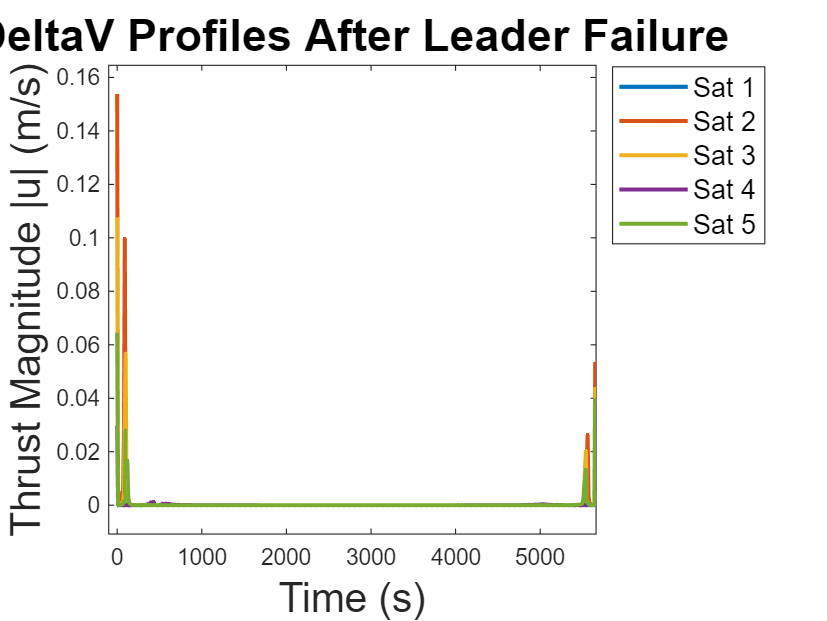


%% === PLOT 2: DELTAV PROFILES ===
figure; hold on;
for i = 1:num_sats
    u = U{i};
    dV = vecnorm(u, 2, 1);
    plot(t_vec(1:end-1), dV, 'LineWidth', 1.8, 'Color', colors(i,:));
end
xlabel('Time (s)', 'FontSize', 18);
ylabel('Thrust Magnitude |u| (m/s)', 'FontSize', 18);
title('DeltaV Profiles After Leader Failure', 'FontSize', 20);
legend(arrayfun(@(i) sprintf('Sat %d', i), 1:num_sats, 'UniformOutput', false), ...
    'Location', 'bestoutside', 'FontSize', 12);
xlim([min(t_vec)-100, max(t_vec)]);
ylim padded 
%grid on; 
box on;
set(gcf, 'Units', 'inches', 'Position', [1, 1, 8, 6]);
exportgraphics(gcf, 'SIM_05_plot2.png', 'Resolution', 300);

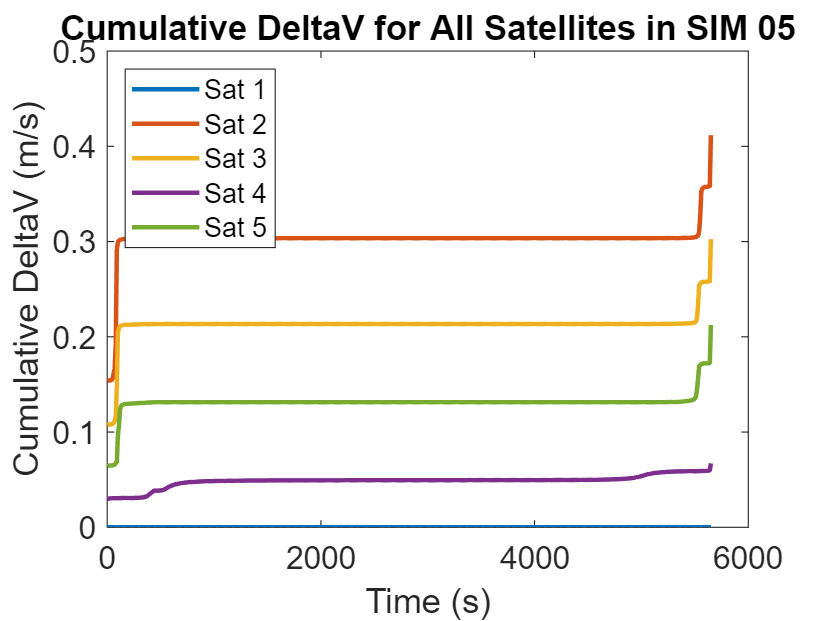


% === PLOT 3: Cumulative DeltaV Over Time ===
figure; hold on;
for i = 1:num_sats
    u = U{i};
    dV_cum = cumsum(vecnorm(u, 2, 1));  % Cumulative sum of normed control input
    plot(t_vec(1:end-1), dV_cum, 'LineWidth', 2, 'Color', colors(i,:), ...
        'DisplayName', ['Sat ' num2str(i)]);
end
xlabel('Time (s)', 'FontSize', 18);
ylabel('Cumulative DeltaV (m/s)', 'FontSize', 18);
title('Cumulative DeltaV for All Satellites in SIM 05', 'FontSize', 20);
legend('FontSize', 12, 'Location', 'northwest');
box on; % grid on;
set(gca, 'FontSize', 14);
set(gcf, 'Units', 'inches', 'Position', [1, 1, 8, 6]);
exportgraphics(gcf, 'SIM_05_plot3.png', 'Resolution', 300);



%% === DELTAV TABLE OUTPUT ===
sat_IDs = (1:num_sats)';
T_dV = table(sat_IDs, dV_total, ...
    'VariableNames', {'Satellite', 'Total_DeltaV_m_per_s'});
disp(' ');

disp('==== Total DeltaV per Satellite ====');

==== Total DeltaV per Satellite ====


disp(T_dV);

    Satellite    Total_DeltaV_m_per_s
    _________    ____________________

        1                     0      
        2               0.41161      
        3               0.30244      
        4              0.067024      
        5               0.21239      




%% === END ===
disp('Simulation completed: SIM_05_LeaderFailure_SwarmReconfig');

Simulation completed: SIM_05_LeaderFailure_SwarmReconfig
